%calculating the mean first passage time using Gillespie simulations 
%to investigate effect of branch migration domai 

%b = 20 %define branch migration domain length
g = 2 %define the invader toehold length  

g = 2


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %define number of simulations

N = 10

avr_first_pass_time = zeros(1,30)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(30, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(30, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 30)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 30)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,30)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through the branch migration length
for b = 10:40

    %define the forward and reverse rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    first_pass_time = zeros(1,N)
    
    %create array of forward and reverse rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
    end
    
    totalrate = Kf + Kb; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition
    Pb = 1-Pf; %define probability of reverse transition
    %loop through the simulations
    for n = 1:N 
        state = 1; %define the initial state
        t = 0; %define the initial time
        %restrict the states which can be reached
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            %calculate whether forward or reverse transition
            if rand() <= Pf(state) 
                state = state +1; %update state forward
            else
                state = state -1; %update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(b-9,n) = first_pass_time(n);
        ind_k_eff(b-9,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(b-9) = std(ind_first_pass_time(b-9, :))/sqrt(N); %calculate standard error
    std_err_k_eff(b-9) = std(ind_k_eff(b-9, :))/sqrt(N);
    std_err_log_k(b-9) = std(log10(ind_k_eff(b-9,:))/sqrt(N));
    avr_first_pass_time(b-9) = mean(first_pass_time) %calculate average first passage time
    k_eff(b-9) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate the effective rate constant
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651    0.7707         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951    2.8486         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651    0.7707    0.7021         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951    2.8486    1.6416         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651    0.7707    0.7021    1.2183         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time = 	1.0e+04 *

    1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468         0         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452         0         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180         0         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421         0         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652         0         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398         0         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130         0         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130    4.1743         0         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979    0.4791         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130    4.1743    5.3855         0         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979    0.4791    0.3714         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130    4.1743    5.3855    5.7189         0


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979    0.4791    0.3714    0.3497         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130    4.1743    5.3855    5.7189    6.2995


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979    0.4791    0.3714    0.3497    0.3175


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


avr_first_pass_time =     1.4947    2.8668    1.5808    2.5951    2.8486    1.6416    2.8240    4.2730    3.5499    3.1978    2.2809    3.6171    2.9605    5.2351    6.1619    4.1465    4.6590    6.9073    6.2799    7.3468    6.8452    8.0180    3.0421    6.6652    6.5398    6.7130    4.1743    5.3855    5.7189    6.2995


k_eff =     1.3381    0.6976    1.2651    0.7707    0.7021    1.2183    0.7082    0.4681    0.5634    0.6254    0.8768    0.5529    0.6756    0.3820    0.3246    0.4823    0.4293    0.2895    0.3185    0.2722    0.2922    0.2494    0.6574    0.3001    0.3058    0.2979    0.4791    0.3714    0.3497    0.3175


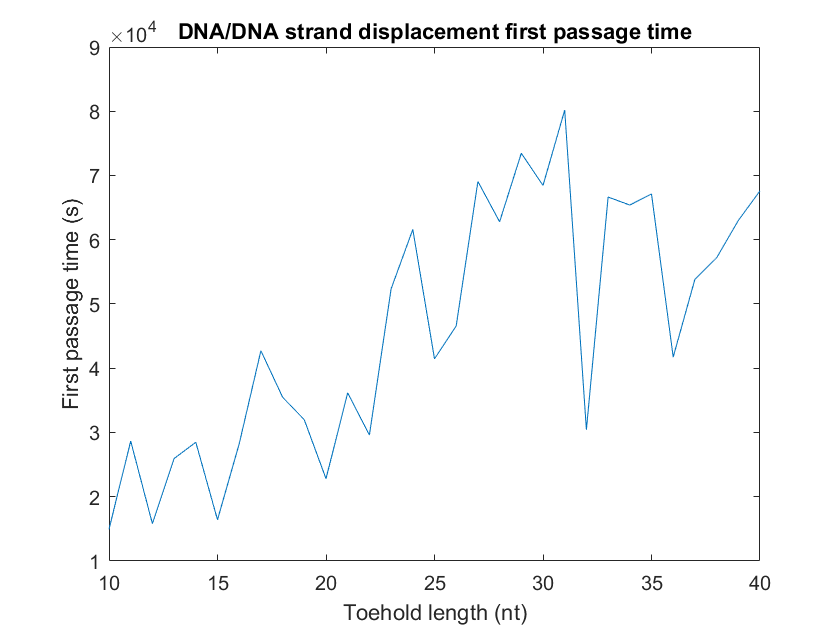

plot(10:40, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

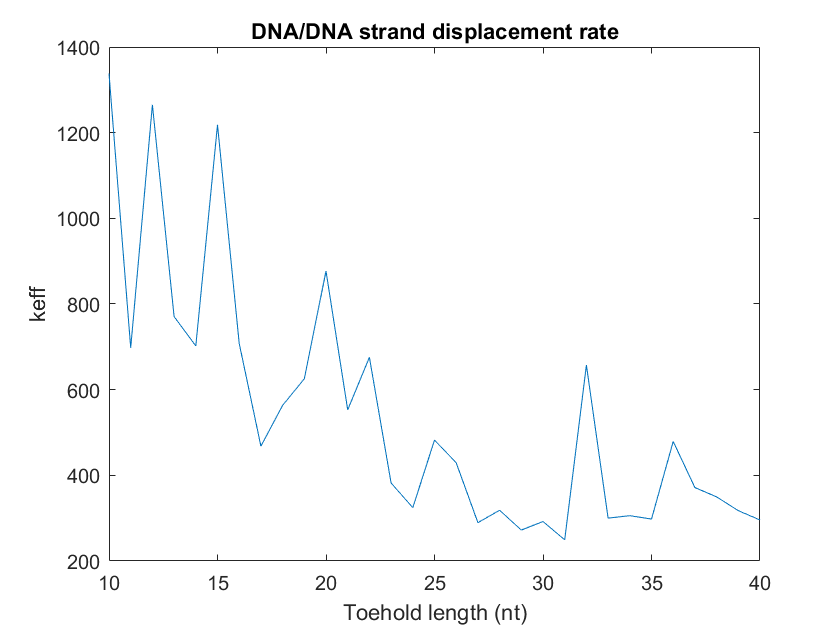


plot(10:40, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

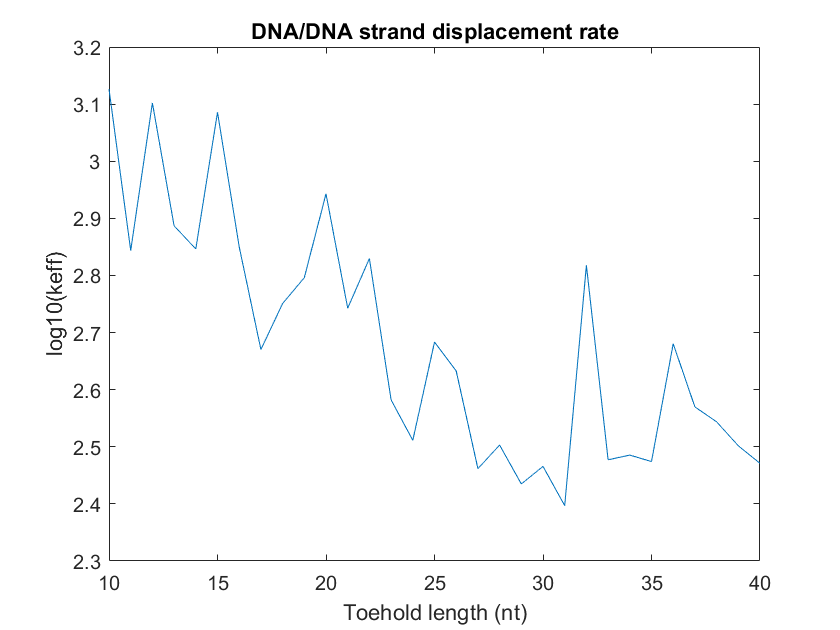


plot(10:40, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

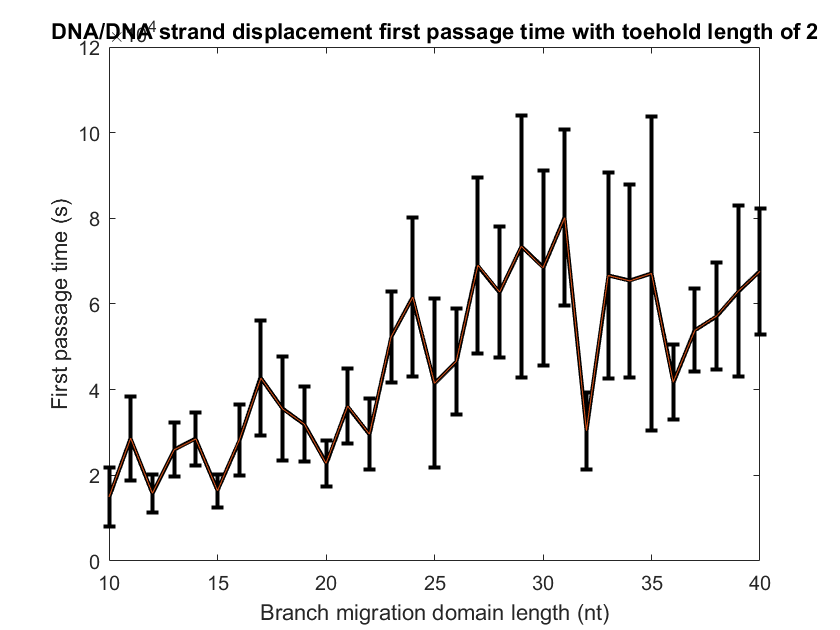


errorbar(10:40, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(10:40, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

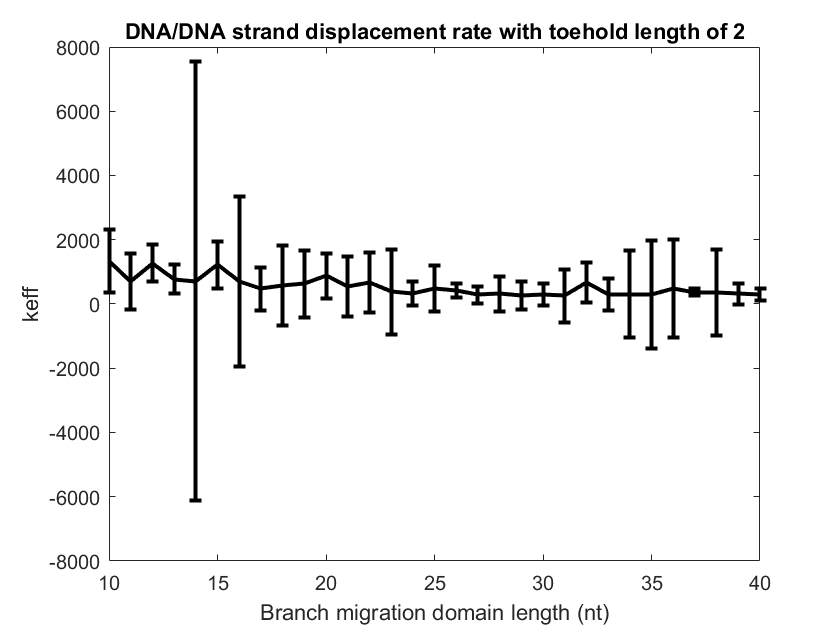


errorbar(10:40, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

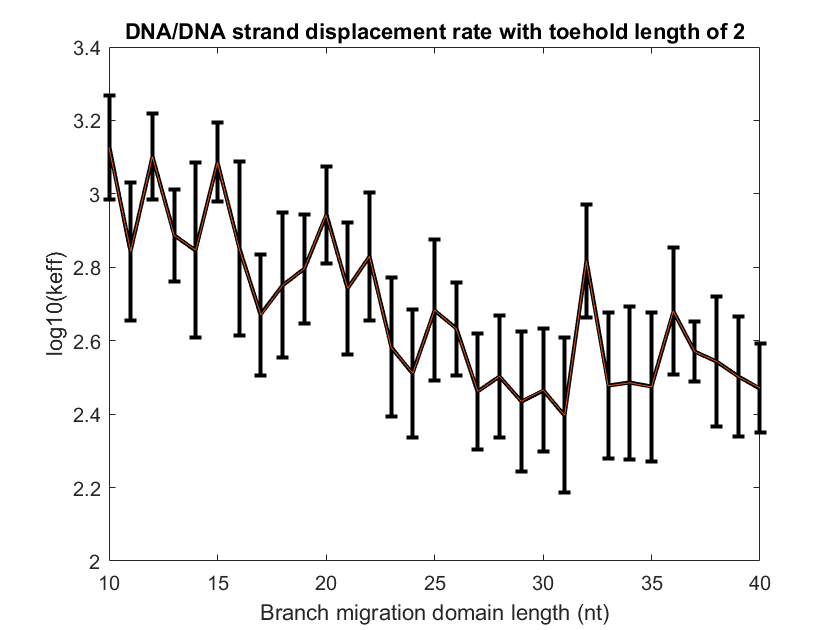


errorbar(10:40, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(10:40, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off